# HINF

Cargar los datos de la función de transferencia

load("../../data/TF.mat"); 

G= Gss;
USSlinmodel = Gss % createUSSmodel(G,20);

USSlinmodel =
 
  A = 
            theta    omega
   theta        0        1
   omega  -0.8957   -3.334
 
  B = 
              u1
   theta       0
   omega  0.9745
 
  C = 
          theta  omega
   theta      1      0
 
  D = 
          u1
   theta   0
 
Continuous-time state-space model.



Error using DynamicSystem/bodemag
Dot indexing is not supported for variables of this type.



freqC1=5;freqC2=32;freqC3=5;

% Selección de filtros 
W1 = makeweight(db2mag(40),[freqC1 db2mag(-10)],db2mag(-50)); % S 
W2  =makeweight(db2mag(-35),[freqC2 db2mag(-32.5)],db2mag(-30)); % KS 
W3 = makeweight(db2mag(-15),[freqC3 db2mag(-10)],db2mag(10)); % T


bodemag(1/W1, 1/W2, 1/W3); 

legend("1/W1", "1/W2","1/W3"); 

legend("Location","best")
grid on


[K_hinf,CL,gamma] = mixsyn(G,W1,W2,W3);
gamma

gamma = 0.5458

Error using DynamicSystem/sigma
Dot indexing is not supported for variables of this type.

S = feedback(1,G*K_hinf);KS = K_hinf*S;T = 1-S;
sigma(S,'r',KS,'g',T,'b',1/W1,'r-.',ss(1/W2),'g-.',1/W3,'b-.',{1e-3,1e3})

legend('S','KS','T','1/W1','1/W2','1/W3','Location','SouthWest')
grid

ALL W

figure()
[K_hinf,CL,gamma]=mixsyn(G,W1,W2,W3);
OL=series(K_hinf,G);
GCL=feedback(OL,1);
GCL.InputName="PWM";
step(GCL)
stepinfo(GCL)
AnchoBanda=bandwidth(GCL)/(2*pi)

### Incertidumbre

SUSS = feedback(1,USSlinmodel*K_hinf);
KSSUSS = K_hinf*SUSS;
TSUSS = 1-SUSS;
sigma(SUSS,'r',KSSUSS,'g',TSUSS,'b',1/W1,'r-.',ss(1/W2),'g-.',1/W3,'b-.',{1e-3,1e3})
legend('S','KS','T','1/W1','1/W2','1/W3','Location','SouthWest')
grid

OLlinUSS=series(K_hinf,USSlinmodel);
GCLlinUSS=feedback(OLlinUSS,1);
GCLlinUSS.InputName="PWM";
GCLlinUSS.OutputName="\theta";
step(GCLlinUSS)
%axis([0 1.2 0 1.2])
hold off
bandwidth(GCLlinUSS)/2/pi
stepinfo(GCLlinUSS)

## Simulación Sistema Lineal

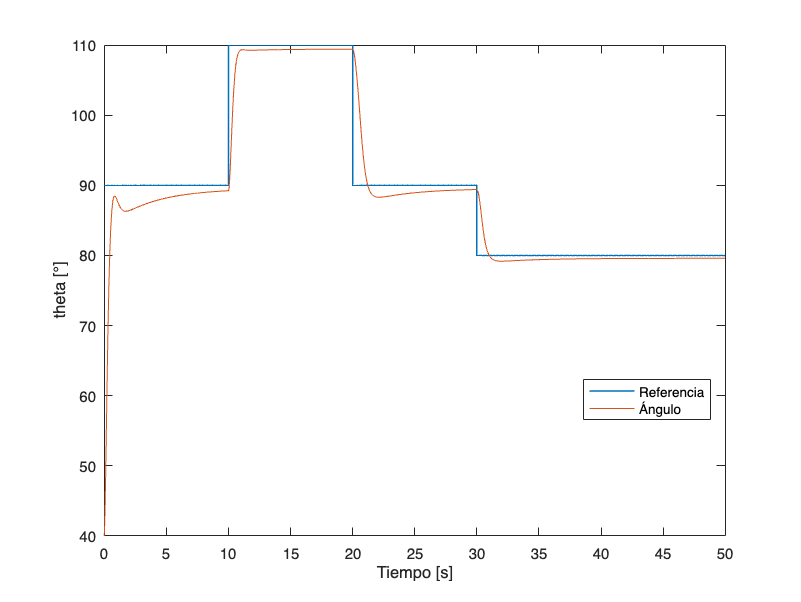

addpath("design"); 
ang_Lin = 40; 
results = sim("hinfSL.slx",50); 

t = results.tout; % tiempo de simulación    

% Estados del sistema
theta = results.theta.Data;
ref = results.Ref.Data;

figure()
plot(t,ref,'-', 'LineWidth',1); 
hold on; 
plot(t,theta);
hold off
xlabel('Tiempo [s]');
ylabel('theta [°]');
legend('Referencia', 'Ángulo','Location','best');

## Simulación Sistema No Lineal

DirectCMD = 40;
results = sim("hinfNL.slx",50); 

t = results.tout; % tiempo de simulación    

% Estados del sistema
theta = results.theta.Data;
ref = results.Ref.Data;

figure()
plot(t,ref,'-', 'LineWidth',1); 
hold on; 
plot(t,theta);
hold off
xlabel('Tiempo [s]');
ylabel('theta [°]');
ylim([60 120])
legend('Referencia', 'Ángulo','Location','best');

## Implementacion en arduino

Convertimos el controldador en ss a espacio discreto para agregarlo al lazo de control de implementación.

Ts = 2.5e-3;  % Tiempo de muestreo

HinfDiscrete = c2d(K_hinf, Ts, 'tustin'); 
save("Hinf", "HinfDiscrete"); 


